## **Author: Sruthi Palaparthi**

## **Last Revision: 12/04/2018**

## **Matlab Version: 2018a**

## ** Version :1**

## **Initialize System for Process**

clc;
clear all;
close all;
format long;

## Initialization Parameters

Here we specify start and stop time in hours and start time of 0.1666 corresponds to 600 seconds (refer schema document for why 600 seconds)

startTime=0.1666;  % Specify in Hours
endTime=4;  % For 30 days change this to 30*24
sTime=startTime*3600*10^6;
eTime=endTime*3600*10^6;
%% Load Data Table
loadDir1='E:\CloudData\clusterdata-2011-2\task_events';
loadDir2='E:\CloudData\clusterdata-2011-2\machine_events';
fileList=dir(strcat(loadDir1,'\*.csv'));
fileList1=dir(strcat(loadDir2,'\*.csv'));
tblCtr=1;
foundFlag=0;


## Reading Machine Data

for flCtr=1:1
    getFileName=strcat(loadDir2,'\',fileList1(flCtr).name);
    mDataTable=readtable(getFileName,'Delimiter',',','ReadVariableNames',false);
    mDataTable.Properties.VariableNames={'Time','MID','EventType','pID','CPU','Mem'};
    mDataTable=mDataTable(:,{'Time','MID','EventType','CPU','Mem'})
     rows=(mDataTable.Time>sTime)&(sum(mDataTable.Time<eTime));
     if (sum(rows)~=0)
        if foundFlag==0
            Table=mDataTable(rows,:);
            foundFlag=1;
        else
            
            Table=[Table;mDataTable(rows,:)];
        end
     else
        if(foundFlag==1)
            break;
        end
    end
end

mDataTable = 37780×5 table
    Time    MID    EventType    CPU     Mem  
    ____    ___    _________    ___    ______

     0       5         0        0.5    0.2493
     0       6         0        0.5    0.2493
     0       7         0        0.5    0.2493
     0      10         0        0.5    0.2493
     0      13         0        0.5    0.2493
     0      14         0        0.5    0.2493
     0      19         0        0.5    0.2493
     0      21         0        0.5    0.2493
     0      23         0        0.5    0.2493
     0      25         0        0.5    0.2493
     0      26         0        0.5    0.2493
     0      27         0        0.5    0.2493
     0      28         0        0.5    0.2493
     0      36         0        0.5    0.2493
     0      37         0        0.5    0.2493
     0      38      

mastMTable=Table

mastMTable = 25303×5 table
       Time          MID        EventType    CPU     Mem  
    __________    __________    _________    ___    ______

     779231019       5782512        1        0.5    0.2493
     974363601    1438195245        2        0.5    0.4995
    1460219913    4820073668        1          1         1
    2071421510       1272981        1        0.5    0.4995
    2580105468     294985247        1        0.5    0.2493
    2975233122    6226704737        2        0.5    0.4995
    3016500490       8631300        1        0.5    0.4995
    3079489506       1272981        0        0.5    0.4995
    3149863049       6567863        2        0.5    0.4995
    3277837725     331141765        0        0.5    0.2493
    3277838708     331141765        2        0.5    0.2493
    3280434685    1785749011       

clear Table;


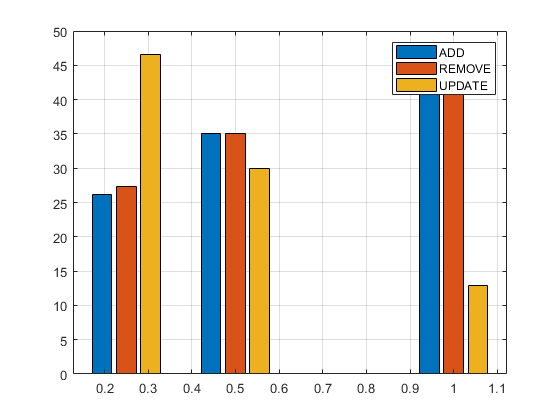


[dt,uniqRws]=unique(mastMTable.MID);
uniqMTable=mastMTable(uniqRws,:);

% figure;
% histogram(uniqMTable.CPU)
% figure;
% histogram(uniqMTable.Mem,100);

 data1 = mastMTable.CPU(mastMTable.EventType==0);
 data2=mastMTable.CPU(mastMTable.EventType==1);
 data3=mastMTable.CPU(mastMTable.EventType==2);
 e=[0.25 0.5 1 1.1];
 h1=histcounts(data1,e);
 h2=histcounts(data2,e);
 h3=histcounts(data3,e);
 hh=[h1;h2;h3]';
%  cpuSums=[sum(mastMTable.CPU==0.25);sum(mastMTable.CPU==0.5);sum(mastMTable.CPU==1)];
cpuSums=sum(hh,2);
cpuSums=repmat(cpuSums,1,3);
 hh=(hh./cpuSums)*100;
 figure;bar(e(1:end-1),hh,'grouped'); legend ('ADD','REMOVE','UPDATE'); grid on;

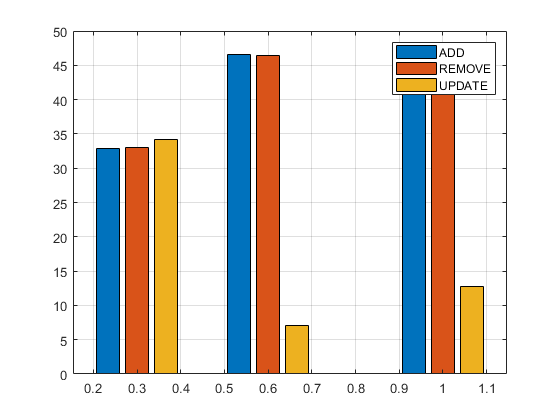

    
e2=[0.030850000000000, 0.061580000000000,0.124100000000000,0.249300000000000,0.249800000000000,0.499500000000000,0.500000000000000,0.749000000000000,0.967800000000000, 1.000000000000000,1.1];
% e1=[e2(1),e2(3),e2(5),e2(7),e2(8),e2(10)]
e1=[0.3,0.6,1,1.1];
data11 = mastMTable.Mem(mastMTable.EventType==0);
 data21=mastMTable.Mem(mastMTable.EventType==1);
 data31=mastMTable.Mem(mastMTable.EventType==2);
   h11=histcounts(data11,e1);
 h21=histcounts(data21,e1);
 h31=histcounts(data31,e1);
 hh1=[h11;h21;h31]';
 memSums=sum(hh1,2);
        
        memSums=repmat(memSums,1,3);
        hh1=(hh1./memSums)*100;
figure;bar(e1(1:end-1),hh1,'grouped'); legend ('ADD','REMOVE','UPDATE'); grid on;

## Separating Task Event Data between Times

%% Separating Between Times
tblCtr=1;
foundFlag=0;

for flCtr=1:500
    getFileName=strcat(loadDir1,'\',fileList(flCtr).name);
    dataTable = readtable(getFileName,'Delimiter',',','ReadVariableNames',false);
    dataTable.Properties.VariableNames={'Time','MissingInfo','JobID','TaskID'...
                                        'MachineID','EventType','User','SchdClass','Priority'...
                                        'CPUReq','MemReq','DskReq','DMR'};
    dataTable=dataTable(:,{'Time','JobID','TaskID','MachineID','EventType','Priority','CPUReq','MemReq'});
     rows=(dataTable.Time>sTime)&(sum(dataTable.Time<eTime));
     if (sum(rows)~=0)
         flCtr
        if foundFlag==0
            Table=dataTable(rows,:);
            foundFlag=1;
        else
            Table=[Table;dataTable(rows,:)];
        end
     else
        if(foundFlag==1)
            break;
        end
    end
end
mastTable=Table; % We store the data in mastTable variable
clear Table;

## This part of the code works on generating boxplots for CPU Req for all 11 priorities

%% Distribution for all priorities
KCPU=-1;
grps=-1;

for i=0:11
    krows=mastTable.Priority==i;
    kCPU{i+1}=table2array(mastTable(krows,'CPUReq'));
    KCPU=[KCPU;kCPU{i+1}];
    grps=[grps;ones(sum(krows),1)*(i+1)];
end
KCPU=KCPU(2:end);
grps=grps(2:end);

## This part of the code segregates priorities into 3 sets 'low',medium and high

figure;boxplot(KCPU,grps,'Symbol','');
%% Distrubution for Priorities 0-1,2-8,9-11
lrows=(mastTable.Priority>=0)&(sum(mastTable.Priority<=3));
mrows=(mastTable.Priority>=4)&(sum(mastTable.Priority<=7));
hrows=(mastTable.Priority>=8)&(sum(mastTable.Priority<=11));
lCPU=table2array(mastTable(lrows,'CPUReq'));
mCPU=table2array(mastTable(mrows,'CPUReq'));
hCPU=table2array(mastTable(hrows,'CPUReq'));
cpuReq=[lCPU;mCPU;hCPU];
grps=[ones(sum(lrows),1);ones(sum(mrows),1)*2;ones(sum(hrows),1)*3];
figure;boxplot(cpuReq,grps,'Symbol','');set(gca,'XTickLabel',{'Low','Medium','High'});

## We also plot the distribution to take a look at machine allotments

figure;subplot(311);hist(lCPU,100000);
subplot(312);hist(mCPU,1000000);subplot(313);hist(hCPU,100000);